clear variables;

demo = false;

## Create Numerical Loops

fex = 100;  % excitation frequency (Hz)
N_cycles = 2;
cycle_points = 600;
m = 10000;
noise = 'fft';
random_value_generator = 'uniform';
training_cycles = N_cycles;

cd ..\create_numerical_loops
numerical_loops = create_loops(fex, N_cycles, cycle_points, m, noise, ...
    random_value_generator, training_cycles);


cd ..\experimental_data
load real_loops.mat;
cd ..\model_1

## Classification using the existing model

pct_train = 0;  % no need to train a new model
[~, loops_test, ~, ~, Xtest, ytest] = choose_features(numerical_loops, ...
                                            'slip', pct_train);

load mdl_classification.mat;
y_pred = predict(mdl_classification, Xtest);
fprintf('Percentage of loops correctly classified: %0.2f%%\n', ...
            mean(y_pred == ytest)*100);

Percentage of loops correctly classified: 99.77%



loops_slip = loops_test(y_pred == 1,:);  % extract loops with gross slip
fprintf('Number of slip: %d | Number of stick: %d\n\n', ...
                            size(loops_slip, 1), m - size(loops_slip, 1));

Number of slip: 8988 | Number of stick: 1012



## Visualise numerical loops

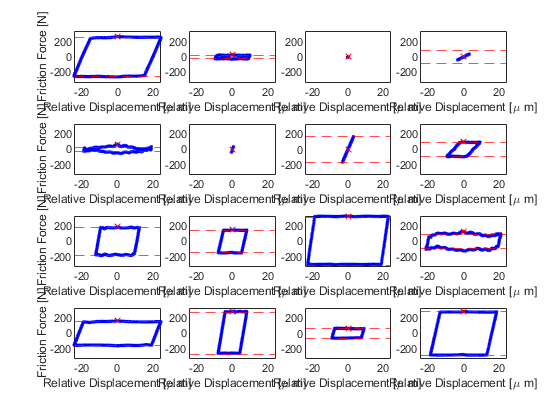

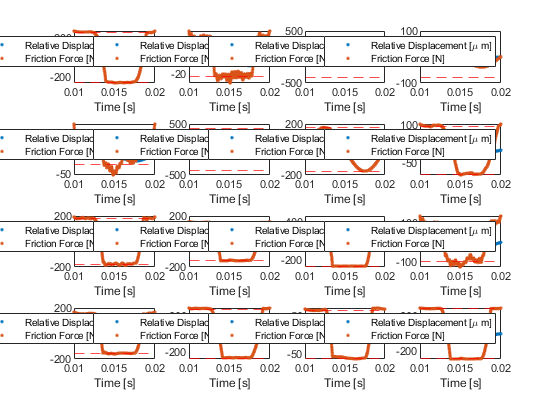

cd ..
normalise = false;
idx = randperm(m, 16);
plot_loops_individual(numerical_loops(idx,:), normalise);

cd model_1

## Choose features for training and testing

pct_train = 0.8;
[~, loops_test, Xtrain, ytrain, Xtest, ytest] = choose_features(loops_slip, ...
                                            'kt_slip', pct_train);

## Train the model

|====================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |       7.983 |      1.4378 |       7.983 |       7.983 |      0.15475 |     0.092652 |       2075.5 |
|    2 | Accept |       7.983 |      1.5866 |       7.983 |       7.983 |       1.2775 |       386.86 |       707.99 |
|    3 | Best   |      7.8565 |      86.926 |      7.8565 |      7.8566 |      0.14424 |       125.15 |      0.16464 |
|    4 | Accept |      7.9832 |      82.129 |      7.8565 |      7.8566 |       32.336 |     0.012078 |        8.162 |
|    5 | Accept |      7.9829 |      87.027 |   

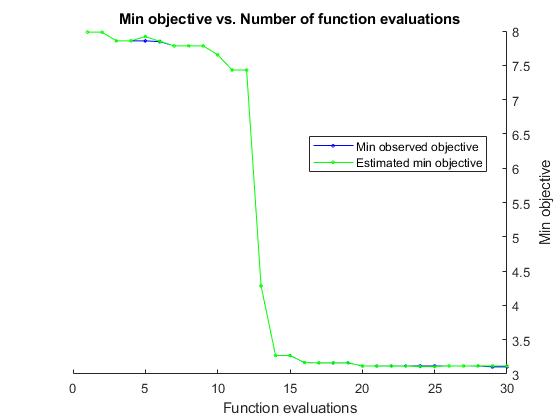


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 3732.1672 seconds
Total objective function evaluation time: 3693.227

Best observed feasible point:
    BoxConstraint    KernelScale    Epsilon 
    _____________    ___________    ________

       946.45          40.038       0.077315

Observed objective function value = 3.1035
Estimated objective function value = 3.1115
Function evaluation time = 336.2268

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale    Epsilon
    _____________    ___________    _______

       998.98          36.333       0.31884

Estimated objective function value = 3.1169
Estimated function evaluation 

mdl_kt_slip =   RegressionSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                                Alpha: [4587×1 double]
                                 Bias: 156.7386
                     KernelParameters: [1×1 struct]
                                   Mu: [1×1200 double]
                                Sigma: [1×1200 double]
                      NumObservations: 7190
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                       BoxConstraints: [7190×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [7190×1 logical]
                               Solver: 'SMO'


  Properties, Methods


if ~demo
rng('default');
mdl_kt_slip = fitrsvm(Xtrain, ytrain,...
            'RemoveDuplicates', false, ...
            'Standardize', true, ...
            'KernelFunction', 'gaussian', ...
            'OptimizeHyperparameters', {'KernelScale', 'BoxConstraint', 'Epsilon'},...
            'HyperparameterOptimizationOptions',...
            struct('AcquisitionFunctionName','expected-improvement-plus'))
end

## Evaluate model performance

if demo
    load mdl_kt_slip.mat
    pct_train = 0;
    [~, loops_test, ~, ~, Xtest, ytest] = choose_features(loops_slip, 'kt_slip', pct_train);
end

fprintf('\n========== slip numerical loops ==========\n');


========== slip numerical loops ==========


if ~demo
    fprintf('Training error: %0.2f%%\n', ...
                mean(abs((predict(mdl_kt_slip, Xtrain)-ytrain)./ytrain))*100);
end

Training error: 0.94%


Convergent with 237959 iterations.
mean error: 2.21%, highest error: 131.13% at 1670
total elapsed time: 3732


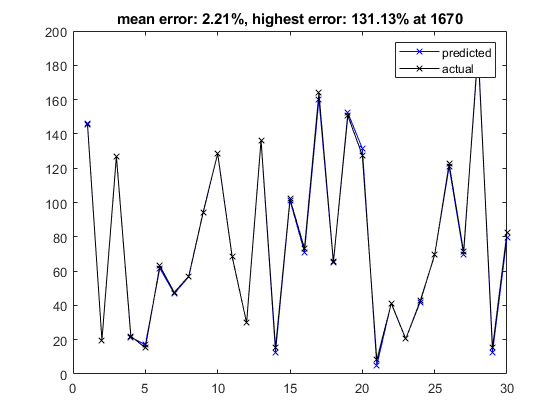

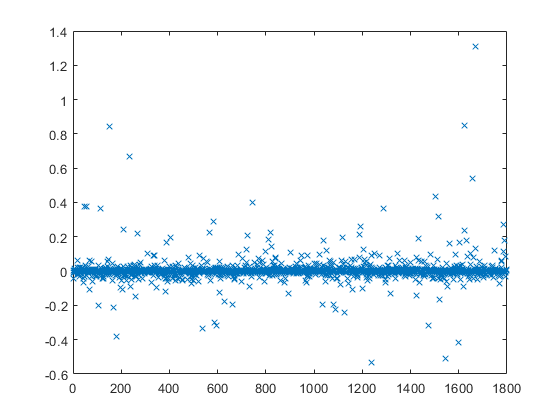


[y_pred, error] = evaluate_mdl_reg(mdl_kt_slip, Xtest, ytest, demo);